clc
clear all
close all
%webcamlist
%preview(cam)
% Create the face detector object.This is the frontal face LBP
%read at : https://in.mathworks.com/help/vision/ref/vision.cascadeobjectdetector-system-object.html#bs_kj0p
%
faceDetector = vision.CascadeObjectDetector('FrontalFaceLBP');
% Create the point tracker object.
pointTracker = vision.PointTracker('MaxBidirectionalError', 2);
% Capture one frame to get its size.
cam = webcam;
videoFrame = snapshot(cam)

videoFrame = 480×640×3 uint8 array
videoFrame(:,:,1) =

     5     8     6     7     8     8     6     6     6     6     7     9     9    10     9     9     9     9     9     9    10    10    10    11    11    11    13    13    12    12    11    11     9     8     6     6     6     7     9     9     9     8     8     8     9    10    13    13    13    12    10     9     9     9     9     9    10    10    12    12    12    12    13    14    14    14    16    14    11    11    13    14    14    14    14    14    14    14    14    15    15    15    15    14    14    14    14    14    14    15    15    17    19    19    20    20    22    22    21    23    22    22    21    20    19    20    21    22    23    23    24    24    24    23    23    22    24    25    25    26    24    24    22    20    17    14    13    14    19    21    22    24    26    28    26    25    25    25    24    25    26    26    26    26    26    26    26    26    27    27    27    27    27    27    25    25    24  

frameSize = size(videoFrame)

frameSize =    480   640     3


% Create the video player object.
videoPlayer = vision.VideoPlayer('Position', [100 100 [frameSize(2), frameSize(1)]+30])

videoPlayer =   vision.VideoPlayer with properties:

        Name: 'Video Player'
    Position: [100 100 670 510]


**create the database.**

cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
         WhiteBalanceMode: 'auto'
                    Gamma: 300
                 Contrast: 50
               Saturation: 50
             ExposureMode: 'auto'
                      Hue: 0
               Brightness: 0
                Sharpness: 50
             WhiteBalance: 4600
                 Exposure: -6
    BacklightCompensation: 0


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                Sharpness: 50
               Saturation: 50
    BacklightCompensation: 0
             WhiteBalance: 4600
                 Contrast: 50
                 Exposure: -6
             ExposureMode: 'auto'
               Brightness: 0
                    Gamma: 300
         WhiteBalanceMode: 'auto'
                      Hue: 0


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                    Gamma: 300
               Brightness: 0
                Sharpness: 50
                 Contrast: 50
         WhiteBalanceMode: 'auto'
    BacklightCompensation: 0
                      Hue: 0
             ExposureMode: 'auto'
                 Exposure: -6
             WhiteBalance: 4600
               Saturation: 50


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
         WhiteBalanceMode: 'auto'
                      Hue: 0
    BacklightCompensation: 0
               Saturation: 50
               Brightness: 0
                    Gamma: 300
                 Contrast: 50
             WhiteBalance: 4600
                Sharpness: 50
             ExposureMode: 'auto'
                 Exposure: -6


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                Sharpness: 50
             WhiteBalance: 4600
               Brightness: 0
               Saturation: 50
                      Hue: 0
                    Gamma: 300
                 Contrast: 50
                 Exposure: -6
         WhiteBalanceMode: 'auto'
             ExposureMode: 'auto'
    BacklightCompensation: 0


cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
                 Exposure: -6
                      Hue: 0
                 Contrast: 50
    BacklightCompensation: 0
         WhiteBalanceMode: 'auto'
                    Gamma: 300
             ExposureMode: 'auto'
                Sharpness: 50
               Saturation: 50
               Brightness: 0
             WhiteBalance: 4600


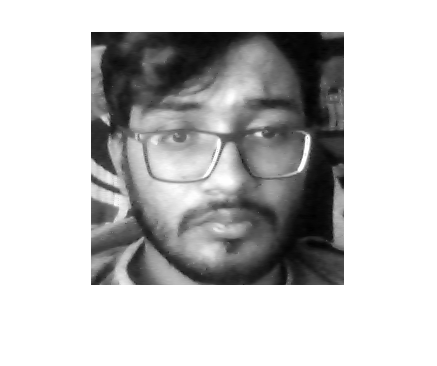

cam =   webcam with properties:

                     Name: 'USB2.0 VGA UVC WebCam'
     AvailableResolutions: {'640x480'  '160x120'  '176x144'  '320x240'  '352x288'}
               Resolution: '640x480'
               Brightness: 0
             WhiteBalance: 4600
                 Contrast: 50
               Saturation: 50
                    Gamma: 300
                      Hue: 0
    BacklightCompensation: 0
         WhiteBalanceMode: 'auto'
                 Exposure: -6
                Sharpness: 50
             ExposureMode: 'auto'


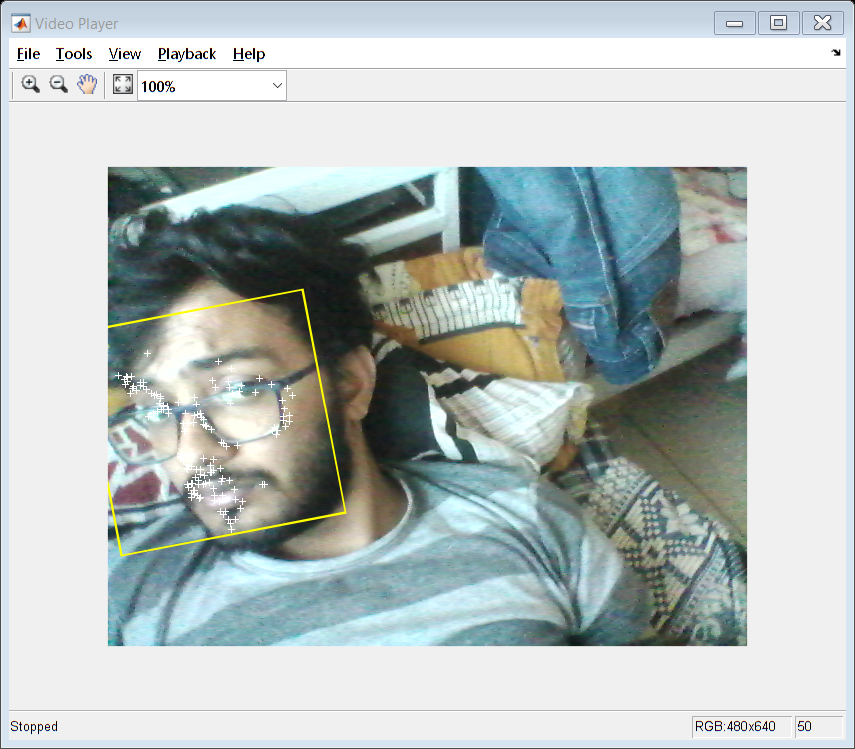

Index in position 2 is invalid. Array indices must be positive integers or logical values.

for j = 62:72
    cam = webcam
    runLoop = true;
    numPts = 0;
    frameCount = 0;
    while runLoop && frameCount < 50
         % Get the next frame.
        videoFrame = snapshot(cam);
        
        % Get frame to save data to database
        videoFrameGray = rgb2gray(videoFrame);
        frameCount = frameCount + 1;
        
        if numPts < 100
            % Detection mode.
            bbox = faceDetector.step(videoFrameGray);
            if ~isempty(bbox)
                % Find corner points inside the detected region.
                points = detectMinEigenFeatures(videoFrameGray, 'ROI', bbox(1, :));
                
                % Re-initialize the point tracker.
                xyPoints = points.Location;
                numPts = size(xyPoints,1);
                release(pointTracker);
                initialize(pointTracker, xyPoints, videoFrameGray);
                
                % Save a copy of the points.
                oldPoints = xyPoints;
                
                % Convert the rectangle represented as [x, y, w, h] into an
                % M-by-2 matrix of [x,y] coordinates of the four corners. This
                % is needed to be able to transform the bounding box to display
                % the orientation of the face.
                bboxPoints = bbox2points(bbox(1, :));
                
                % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
                % format required by insertShape.
                bboxPolygon = reshape(bboxPoints', 1, []);
                
                % Display a bounding box around the detected face.
                videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);
                
                % Display detected corners.
                videoFrame = insertMarker(videoFrame, xyPoints, '+', 'Color', 'blue');
            end
            
      else
            % Tracking mode.
            [xyPoints, isFound] = step(pointTracker, videoFrameGray);
            visiblePoints = xyPoints(isFound, :);
            oldInliers = oldPoints(isFound, :);
            numPts = size(visiblePoints, 1);
            if numPts >= 100
                % Estimate the geometric transformation between the old points
                % and the new points.
                [xform, oldInliers, visiblePoints] = estimateGeometricTransform(...
                    oldInliers, visiblePoints, 'similarity', 'MaxDistance', 4);
                % Apply the transformation to the bounding box.
                bboxPoints = transformPointsForward(xform, bboxPoints);
                % Convert the box corners into the [x1 y1 x2 y2 x3 y3 x4 y4]
                % format required by insertShape.
                bboxPolygon = reshape(bboxPoints', 1, []);
                
                % Display a bounding box around the face being tracked.
                videoFrame = insertShape(videoFrame, 'Polygon', bboxPolygon, 'LineWidth', 3);
                % Display tracked points.
                videoFrame = insertMarker(videoFrame, visiblePoints, '+', 'Color', 'white');
                % Reset the points.
                oldPoints = visiblePoints;
                setPoints(pointTracker, oldPoints);
            end
        end
        
          % Display the annotated video frame using the video player object.
        step(videoPlayer, videoFrame);
        % Check whether the video player window has been closed.
        runLoop = isOpen(videoPlayer);
    end
    % Clean up.
    clear cam;
    release(videoPlayer);
    release(pointTracker);
    release(faceDetector);
    
    % saving the image to database
    position1 = min(bboxPolygon(2),bboxPolygon(4));
    position2 = max(bboxPolygon(6),bboxPolygon(8));
    position3 = min(bboxPolygon(1),bboxPolygon(7));
    position4 = max(bboxPolygon(3),bboxPolygon(5));
    warning('off')
    getimage = videoFrameGray(position1:position2,position3:position4,:);
    imshow(getimage)
    %resize image
    getimage = imresize(getimage, [300 300]);
    % Modify here. In the folder database2, label the name of ppl and put their
    % faces inside the folder.
    sprintf('image%d', j);
    imwrite(getimage,strcat('Rohit',num2str(j),'.jpg'),'jpg');
    pause(1)
end 